# Max-Plus Linear (MPL) Systems: Modeling and Simulation

Before proceeding, install the free Max-Plus Algebra Toolbox for Matlab from [http://www.stanczyk.pro/mpa](http://www.stanczyk.pro/mpa).

## Defining a Max-Plus Linear (MPL) System

We consider a system defined by


$$\begin{array}{l}
x_k =A\otimes x_{k-1} \oplus B\otimes u_k \\
y_k =C\otimes x_k 
\end{array}$$


and parameterized by the triple of matrices A, B, and C

A = [12 mp_zero mp_zero;
     mp_zero 11 mp_zero;
     24 23 7]

A =     12  -Inf  -Inf
  -Inf    11  -Inf
    24    23     7


B = [0; 2; 14]

B =      0
     2
    14


C = [mp_zero mp_zero 7]

C =   -Inf  -Inf     7


## (Some) analysis of the systems

mp_is_pgsc1(A)

ans = 0

Not this time :-) 

## Parameters for the simulation

We assume the initial state zero

x0 = mp_zeros(3, 1);

And we consider the following input sequence for which we are going to compute the response

u = [1; 8; 15; 19]

u =      1
     8
    15
    19


## Simulation

We now computing the response by repeatedly applying the state update equation and the output equation 

X(:, 1)= mp_add(mp_multi(A, x0), mp_multi(B, u(1)));
Y(1) = mp_multi(C, X(:,1));

for i = 2:4
    X(:, i)= mp_add(mp_multi(A, X(:,i-1)), mp_multi(B, u(i)));
    Y(i) = mp_multi(C, X(:, i));
end

X, Y

X =      1    13    25    37
     3    14    25    36
    15    26    37    49


Y =     22    33    44    56


Equivalently, we can build the matrix that relates the input and output sequences (well, it could certainly be done programmatically, here it is just "hardwired" for the 4x4 size)

H = [mp_multi(C,B) mp_zero mp_zero mp_zero;
     mp_multi(C,mp_multi(A,B)) mp_multi(C,B) mp_zero mp_zero;
     mp_multi(C,mp_multi(mp_power(A,2),B)) mp_multi(C,mp_multi(mp_power(A,1),B)) mp_multi(C,B) mp_zero;
     mp_multi(C,mp_multi(mp_power(A,3),B)) mp_multi(C,mp_multi(mp_power(A,2),B)) mp_multi(C,mp_multi(mp_power(A,1),B)) mp_multi(C,B)]

H =     21  -Inf  -Inf  -Inf
    32    21  -Inf  -Inf
    43    32    21  -Inf
    55    43    32    21


Using this matrix, the simulation can be run simply by multiplying the input sequence by the matrix

y = mp_multi(H,u)

y =     22
    33
    44
    56


## Simple residuation-based reference tracking controller

The reference signal is

r = [21; 32; 48; 55]

r =     21
    32
    48
    55


The sequence that generates this reference can be computed by solving the equation $u=H^{-1} r$

u_s = mp_solve_Axb(H,r)

u_s =      0
    11
    23
    34


Observe now that in this particular case the computed control input does not exactly generate the reference output but only a *subsolution*

y_s = mp_multi(H,u_s)

y_s =     21
    32
    44
    55


The tracking error is

e_s = r-y_s

e_s =      0
     0
     4
     0


The maximum deviation is

delta = max(e_s)

delta = 4

A control sequence that minimizes the tracking error can be computed by 

u_d = mp_multi(u_s,delta/2)

u_d =      2
    13
    25
    36


The corresponding output is

y_d = mp_multi(H,u_d)

y_d =     23
    34
    46
    57


The regulation error in this case is

e_d = r-y_d

e_d =     -2
    -2
     2
    -2


Obviously the error is smaller than in the previous case.

## MPC for MPL systems

clear all

Define the matrices for the MPL system

A = [12 mp_zero mp_zero;
     mp_zero 11 mp_zero;
     24 23 7];
B = [0; 2; 14];
C = [mp_zero mp_zero 7];

We set the horizon N

N = 15;

We also set some nonzero initial state (within the receding horizon control methodology this will inevitably be the case)

x0 = [0; 2; 14];

The only optimization variable is the vector u. We now use Yalmip to define such optimization variable 

u = sdpvar(N,1);

The only inequality constraints are the lower and upper bounds on $\Delta \;u_k =u_k -u_{k-1}$. But we need to initialize the sequence u with an artificial 0th element

u0 = 15;
constraints = [0 <= diff([u0;u]) <= 15];

The reference is

r = [14, 33, 57, 76, 85, 108, 108, 108, 126, 140, 154, 168, 182, 196, 210, 224]';

The weight

lambda = 0.05;

Build the MPC optimization problem

obj = 0;
x{1} = x0;
for i = 1:N
    x{i+1} = tplus(ttimes(A,x{i}),ttimes(B,u(i)));
    y{i} = ttimes(C,x{i});
    obj = obj + max([0 y{i} - r(i)]) - lambda*u(i);    
end
y{N + 1} = ttimes(C,x{N+1});
obj = obj + max([0 y{N+1}-r(N+1)]);

The optimization problem is now built, let's optimize

sol = optimize(constraints,obj)

MOSEK Version 9.3.20 (Build date: 2022-4-27 08:19:36)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : LO (linear optimization problem)
  Constraints            : 87              
  Cones                  : 0               
  Scalar variables       : 188             
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name      

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.12.0.1884302 (R2022a)'
       yalmiptime: 5.1901
       solvertime: 0.1162
             info: 'Successfully solved (MOSEK)'
          problem: 0


The resulting optimal control input is

u_mpc = value(u)

u_mpc =    15.0000
   29.0000
   41.0000
   53.0000
   65.0000
   76.0000
   87.0000
  102.0000
  117.0000
  132.0000


The corresponding output needs to be obtained by simulation since the x and y variables were eliminated from the optimization

x_mpc(:, 1)= mp_add(mp_multi(A, x0), mp_multi(B, u_mpc(1)));
y_mpc(1) = mp_multi(C, x_mpc(:,1));

for i = 2:N
    x_mpc(:, i)= mp_add(mp_multi(A, x_mpc(:,i-1)), mp_multi(B, u_mpc(i)));
    y_mpc(i) = mp_multi(C, x_mpc(:, i));
end

The results

x_mpc, y_mpc

x_mpc =    15.0000   29.0000   41.0000   53.0000   65.0000   77.0000   89.0000  102.0000  117.0000  132.0000  147.0000  161.0000  175.0000  189.0000  203.0000
   17.0000   31.0000   43.0000   55.0000   67.0000   78.0000   89.0000  104.0000  119.0000  134.0000  149.0000  163.0000  177.0000  191.0000  205.0000
   29.0000   43.0000   55.0000   67.0000   79.0000   90.0000  101.0000  116.0000  131.0000  146.0000  161.0000  175.0000  189.0000  203.0000  217.0000


y_mpc =    36.0000   50.0000   62.0000   74.0000   86.0000   97.0000  108.0000  123.0000  138.0000  153.0000  168.0000  182.0000  196.0000  210.0000  224.0000


## Plotting the results

The control input

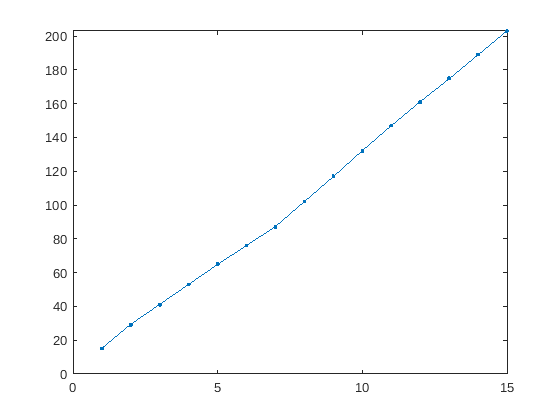

plot(u_mpc,'.-')

The output and the reference

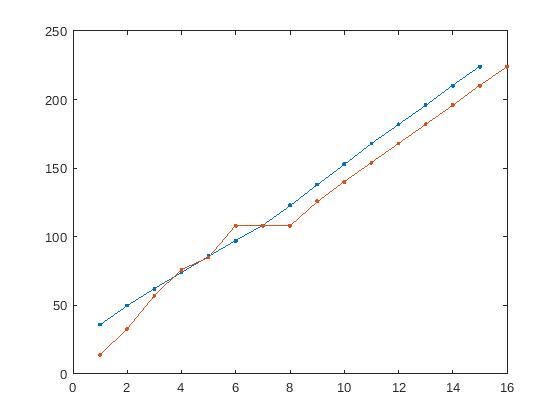

plot(y_mpc,'.-')
hold on
plot(r,'.-')
hold off

The regulation error

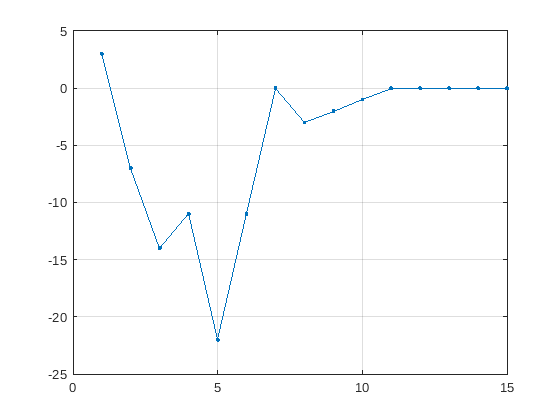

e_mpc = y_mpc'-r(2:end);
plot(e_mpc,'.-'), grid on

## References

- De Schutter, Bart, and Ton van den Boom. "Model Predictive Control for Max-plus-Linear Discrete Event Systems." Automatica 37, no. 7 (July 1, 2001): 1049–56. [https://doi.org/10.1016/S0005-1098(01)00054-1](https://doi.org/10.1016/S0005-1098(01)00054-1).

- ———. "Model Predictive Control for Max-plus-Linear Discrete-Event Systems: Extended Report & Addendum." Technical report. Control Systems Engineering. Delft, The Netherlands: Delft University of Technology, November 2000. [https://pub.deschutter.info/abs/99_10a.html](https://pub.deschutter.info/abs/99_10a.html).

- De Schutter, Bart, Ton van den Boom, Jia Xu, and Samira S. Farahani. "Analysis and Control of Max-plus Linear Discrete-Event Systems: An Introduction." Discrete Event Dynamic Systems 30, no. 1 (March 1, 2020): 25–54. [https://doi.org/10.1007/s10626-019-00294-w](https://doi.org/10.1007/s10626-019-00294-w).